# **Modelo de red convolucional tipo DnCNN (denoising)**

clc; clear all;

enable_Train = true;
data = load("X_train1.mat");
label = load("Y_train1.mat");

%Se importan los datos y las variables asociadas con los datos para el
%entrenamiento
data = data.x_train;
label = label.y_train;

size(label)

ans =          624          14           2       10000


label = data - label;
size(label)

ans =          624          14           2       10000


[subport, simbolos, valor] = size(label)

subport = 624

simbolos = 14

valor = 20000


ratio = 0.75; %Porcentaje para la separación de los datos

[trainId,~,testId] = dividerand(10000,ratio,0.0,1-ratio);

x_train = data(:,:,:,trainId);
y_train = label(:,:,:,trainId);

x_val = data(:,:,:,testId);
y_val = label(:,:,:,testId);


x_train = cat(4, x_train(:,:,1,:), x_train(:,:,2,:));
y_train = cat(4, y_train(:,:,1,:), y_train(:,:,2,:));

x_test = cat(4, x_val(:,:,1,:), x_val(:,:,2,:));
y_test = cat(4, y_val(:,:,1,:), y_val(:,:,2,:));

input_Layer = imageInputLayer([subport simbolos 1], "Name",'Entrada')

input_Layer =   ImageInputLayer with properties:

                      Name: 'Entrada'
                 InputSize: [624 14 1]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []



layers = dnCNNLayers

layers =   1×59 Layer array with layers:

     1   'InputLayer'             Image Input           50×50×1 images
     2   'Conv1'                  2-D Convolution       64 3×3×1 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'ReLU1'                  ReLU                  ReLU
     4   'Conv2'                  2-D Convolution       64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'BNorm2'                 Batch Normalization   Batch normalization with 64 channels
     6   'ReLU2'                  ReLU                  ReLU
     7   'Conv3'                  2-D Convolution       64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'BNorm3'                 Batch Normalization   Batch normalization with 64 channels
     9   'ReLU3'                  ReLU                  ReLU
    10   'Conv4'                  2-D Convolution       64 3×3×64 convolu

l_graph = layerGraph(layers)

l_graph =   LayerGraph with properties:

     InputNames: {'InputLayer'}
    OutputNames: {'FinalRegressionLayer'}
         Layers: [59×1 nnet.cnn.layer.Layer]
    Connections: [58×2 table]


l_graph = replaceLayer(l_graph, 'InputLayer', input_Layer)

l_graph =   LayerGraph with properties:

     InputNames: {'Entrada'}
    OutputNames: {'FinalRegressionLayer'}
         Layers: [59×1 nnet.cnn.layer.Layer]
    Connections: [58×2 table]


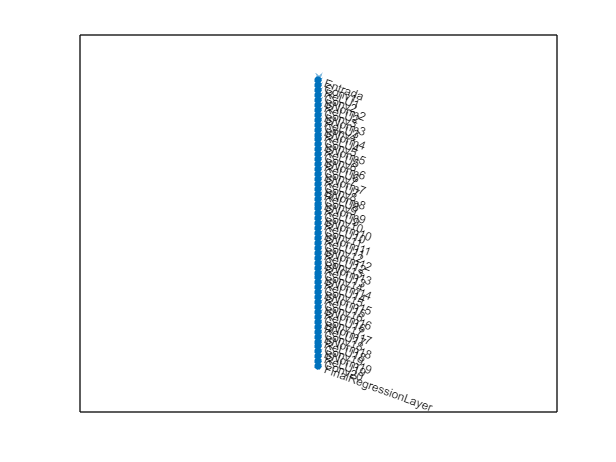

plot(l_graph)

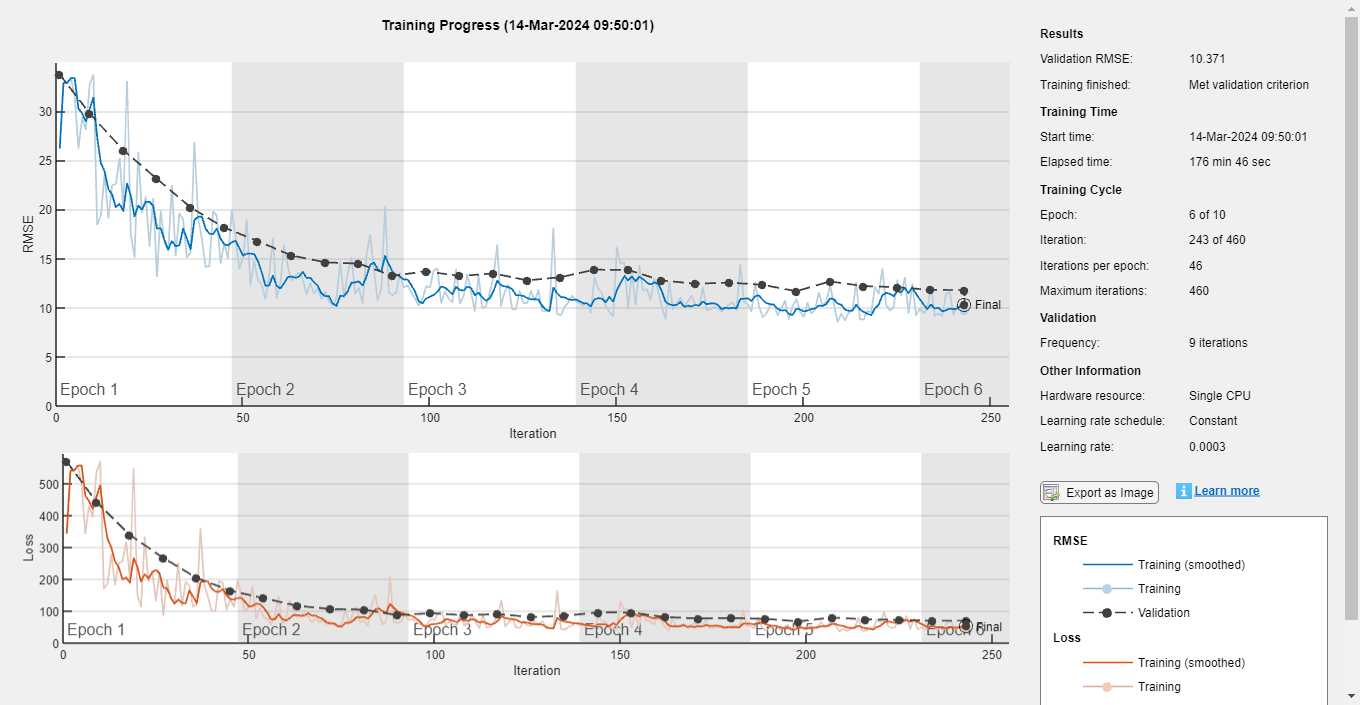

if enable_Train
    batch = 32; % Es el número de ejemplos que se introducen en la red.
    
    %Esta variable se usa para verificar 5 veces en cada época.
    valFrequency = round(size(x_train,4)/batch/5); 


    %Aquí se puede definir las capas que van a componer la RNA

    hiper_param = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',10, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batch, ...
        'ValidationData',{x_test, y_test}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);


    [estimacionRNA, infoRNA] = trainNetwork(x_train, ...
        y_train,l_graph,hiper_param);

    save('Denoising2.mat', "estimacionRNA");

else
    load("Denoising2.mat");
end